# Praktikum 5 Computational Geometry

Tobias Gruber & Christopher Hinz

% Clear workspace
clearvars
close all
format compact
clc

Daten einlesen.

data_tp = readtable(fullfile(".", "testpolygon.txt"));
data_p  = readtable(fullfile(".", "polygon.txt"));

data_tp.Properties.VariableNames = {'x', 'y'};
data_p.Properties.VariableNames  = {'x', 'y'};

Polygone plotten.

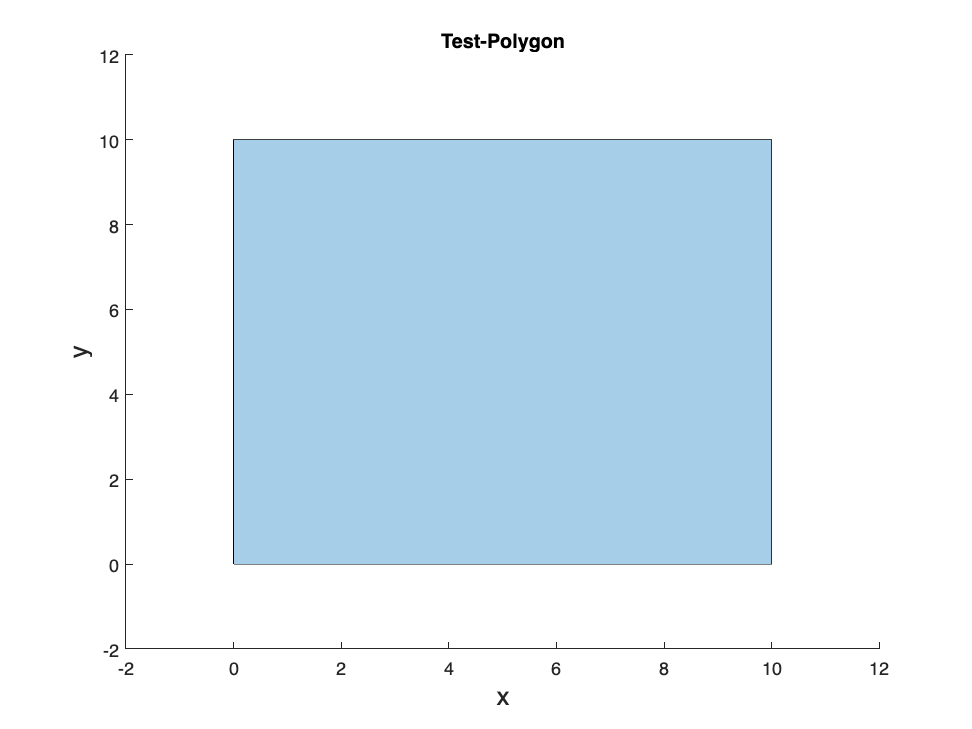

testpolygon = polyshape(data_tp.x, data_tp.y);
plot(testpolygon);
title('Test-Polygon');
xlabel('x', 'FontSize', 14);
ylabel('y', 'FontSize', 14);

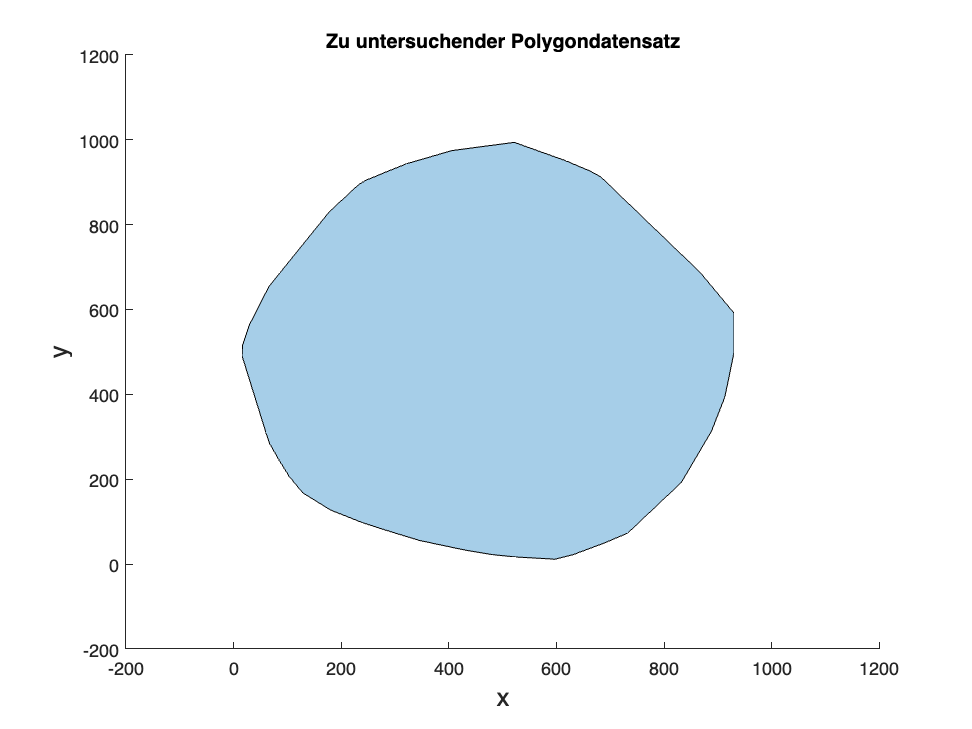


polygon = polyshape(data_p.x, data_p.y);
plot(polygon);
title('Zu untersuchender Polygondatensatz');
xlabel('x', 'FontSize', 14);
ylabel('y', 'FontSize', 14);

Berechnung mit Testdatensatz.

syms nx ny

for i = 1:height(data_tp)-1
    % Gleichungssystem mit der Bedingung, dass Normalenvektor senkrecht zum
    % Richtungsvektor der Streckenpunkte ist und dass die Länge des Vektors
    % 1 beträgt.
    equ = [0 == (data_tp.y(i) - data_tp.y(i+1))*ny + (data_tp.x(i) - data_tp.x(i+1))*nx, nx^2 + ny^2 == 1];
    s = solve(equ, [nx, ny]);
    
    % Auswahl des Normalenvektors der nach innen zeigt
    n(i,:) = chooseVec(data_tp, i, i+1, s);
    d(i) = -n(i,1)*data_tp.x(i) - n(i,2)*data_tp.y(i);

    % Wenn Anfangs- und Endpunkt nicht gleich sind, muss eine weitere Gerade
    % überprüft werden.
    if (i == height(data_tp)-1) && ((data_tp.y(i+1) ~= data_tp.y(1)) || (data_tp.x(i+1) ~= data_tp.x(1)))
        i = i + 1;
        equ = [0 == (data_tp.y(i) - data_tp.y(1))*ny + (data_tp.x(i) - data_tp.x(1))*nx, nx^2 + ny^2 == 1];
        s = solve(equ, [nx, ny]);
        
        % Auswahl des Normalenvektors der nach innen zeigt
        n(i,:) = chooseVec(data_tp, i, 1, s);
        d(i) = -n(i,1)*data_tp.x(i) - n(i,2)*data_tp.y(i);
    end
end

Festlegen der Zielfunktion, sowie der Randbedingungen.

% Randbedingungen
A = [-double(n), ones(height(n),1)]

A =      0    -1     1
     1     0     1
     0     1     1
    -1     0     1


b = -double(d)

b =      0   -10   -10     0



% Zielfunktion
ct = [0, 0, -1];

xyr = -linprog(ct, A, b)

Optimal solution found.



xyr =      5
     5
     5


Plot des Testdatensatzes mit gefundenem Kreis.

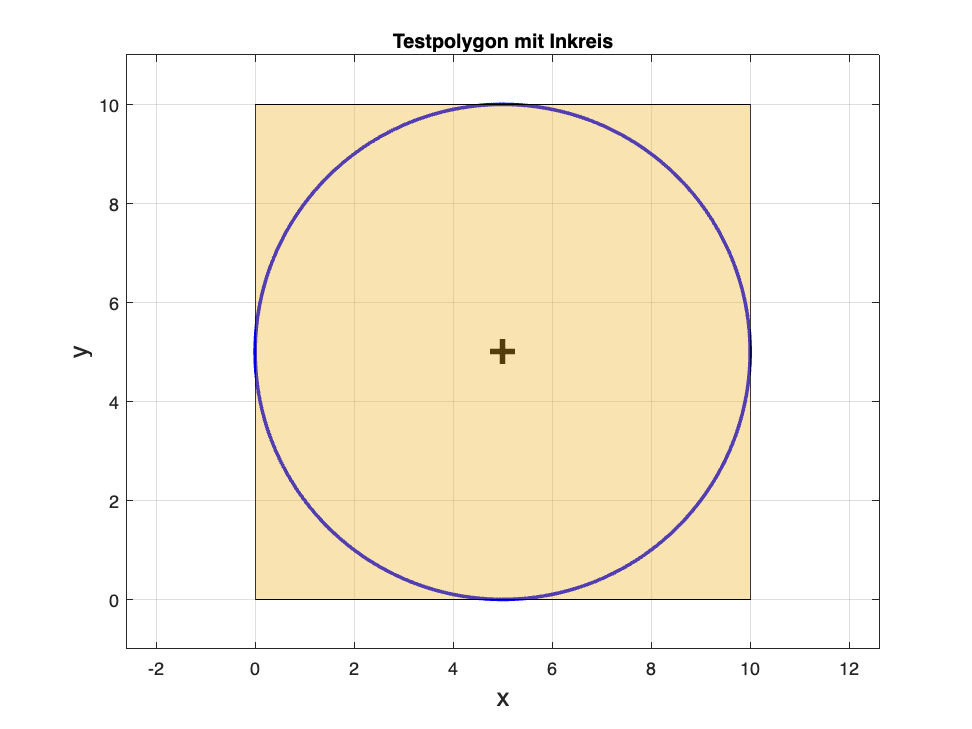

angles = linspace(0, 2*pi, 500);

X = xyr(3) * cos(angles) + xyr(1);
Y = xyr(3) * sin(angles) + xyr(2);

plot(X, Y, 'b-', 'LineWidth', 2);
hold on;
plot(xyr(1), xyr(2), 'k+', 'LineWidth', 3, 'MarkerSize', 14);
grid on;
axis equal;
plot(testpolygon)
title('Testpolygon mit Inkreis');
xlabel('x', 'FontSize', 14);
ylabel('y', 'FontSize', 14);
hold off;

Berechnung mit dem richtigen Datensatz.

syms nx ny

for i = 1:height(data_p)-1
    % Gleichungssystem mit der Bedingung, dass Normalenvektor senkrecht zum
    % Richtungsvektor der Streckenpunkte ist und dass die Länge des Vektors
    % 1 beträgt.
    equ = [0 == (data_p.y(i) - data_p.y(i+1))*ny + (data_p.x(i) - data_p.x(i+1))*nx, nx^2 + ny^2 == 1];
    s = solve(equ, [nx, ny]);
    
    % Auswahl des Normalenvektors der nach innen zeigt
    n(i,:) = chooseVec(data_p, i, i+1, s);
    d(i) = -n(i,1)*data_p.x(i) - n(i,2)*data_p.y(i);

    % Wenn Anfangs- und Endpunkt nicht gleich sind, muss eine weitere Gerade
    % überprüft werden.
    if (i == height(data_p)-1) && ((data_p.y(i+1) ~= data_p.y(1)) || (data_p.x(i+1) ~= data_p.x(1)))
        equ = [0 == (data_p.y(i) - data_p.y(1))*ny + (data_p.x(i) - data_p.x(1))*nx, nx^2 + ny^2 == 1];
        s = solve(equ, [nx, ny]);
        
        % Auswahl des Normalenvektors der nach innen zeigt
        n(i+1,:) = chooseVec(data_p, i, 1, s);
        d(i+1) = -n(i+1,1)*data_p.x(i) - n(i+1,2)*data_p.y(i);
    end
end

% Randbedingungen
A = [-double(n), ones(height(n),1)];
b = -double(d);

% Zielfunktion
ct = [0, 0, -1];

xyr = -linprog(ct, A, b)

Optimal solution found.



xyr =   472.5705
  476.6642
 -438.5922


Plot Polygon mit Kreis.

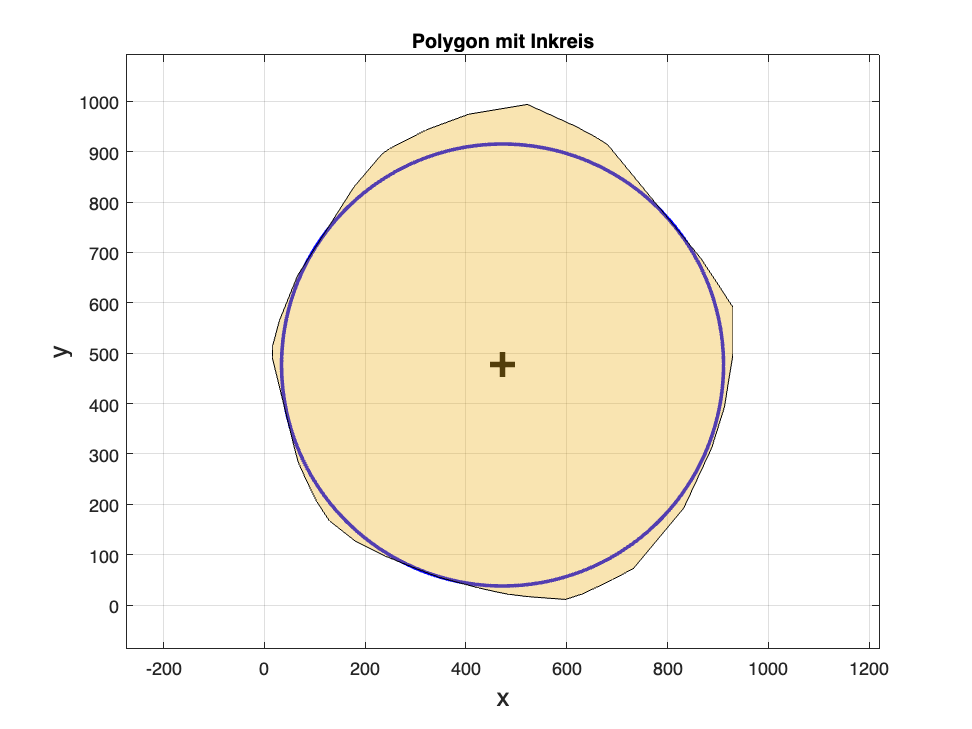

angles = linspace(0, 2*pi, 500);

X = xyr(3) * cos(angles) + xyr(1);
Y = xyr(3) * sin(angles) + xyr(2);

plot(X, Y, 'b-', 'LineWidth', 2);
hold on;
plot(xyr(1), xyr(2), 'k+', 'LineWidth', 3, 'MarkerSize', 14);
grid on;
axis equal;
plot(polygon)
title('Polygon mit Inkreis');
xlabel('x', 'FontSize', 14);
ylabel('y', 'FontSize', 14);
hold off;